# Fit and Predict workspace firing from different models

## Add stuff to path

if(ispc)
    homeFolder = 'C:\Users\Raeed\';
else
    homeFolder = '/home/raeed/';
end
% addpath(genpath('C:\Users\Raeed\Projects\limblab\ClassyDataAnalysis'))
% addpath(genpath('/home/raeed/Projects/limblab/ClassyDataAnalysis'))
addpath(genpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'ClassyDataAnalysis']))
addpath([homeFolder filesep 'Projects' filesep 'limblab' filesep 'proc-raeed' filesep 'MultiWorkspace' filesep 'lib' filesep])
cd([homeFolder 'Projects' filesep 'limblab' filesep 'data-raeed' filesep 'MultiWorkspace' filesep 'SplitWS' filesep 'Han' filesep '20160322' filesep 'area2' filesep])

Error using cd
Cannot CD to C:\Users\rhc307\Projects\limblab\data-raeed\MultiWorkspace\SplitWS\Han\20160322\area2\ (Name is nonexistent or not a directory).


% addpath('/home/raeed/Projects/limblab/proc-raeed/MultiWorkspace/lib/')
% cd('/home/raeed/Projects/limblab/data-raeed/MultiWorkspace/SplitWS/Han/20160322/area2/')

## Load CDS files

cds_files = dir(['CDS' filesep '*.mat']);

for i = 1:numel(cds_files)
    load(['CDS' filesep cds_files(i).name])
end


clear i
clear cds_files


## Add CDS files to experiments and bin data

% DL stuff
DL_ex = experiment();

% set variables to load from cds
DL_ex.meta.hasLfp=false;
DL_ex.meta.hasKinematics=true;
DL_ex.meta.hasForce=false;
DL_ex.meta.hasUnits=true;
DL_ex.meta.hasTrials=true;
DL_ex.meta.hasAnalog=true;
% add session to experiment
DL_ex.addSession(DL_cds);

% Bin experiment data
DL_ex.binConfig.include(1).field='units';
DL_ex.binConfig.include(1).which=find([DL_ex.units.data.ID]>0 & [DL_ex.units.data.ID]<255);
DL_ex.binConfig.include(2).field='kin';
DL_ex.binConfig.include(2).which={};
DL_ex.binConfig.include(3).field='analog';
DL_ex.binConfig.include(3).which=DL_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
DL_ex.firingRateConfig.cropType='tightCrop';
DL_ex.firingRateConfig.offset=-0.015;

DL_ex.binData()


% PM stuff
PM_ex = experiment();

% set variables to load from cds
PM_ex.meta.hasLfp=false;
PM_ex.meta.hasKinematics=true;
PM_ex.meta.hasForce=false;
PM_ex.meta.hasUnits=true;
PM_ex.meta.hasTrials=true;
PM_ex.meta.hasAnalog=true;
% add session to experiment
PM_ex.addSession(PM_cds);

PM_ex.binConfig.include(1).field='units';
PM_ex.binConfig.include(1).which=find([PM_ex.units.data.ID]>0 & [PM_ex.units.data.ID]<255);
PM_ex.binConfig.include(2).field='kin';
PM_ex.binConfig.include(2).which={};
PM_ex.binConfig.include(3).field='analog';
PM_ex.binConfig.include(3).which=PM_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
PM_ex.firingRateConfig.cropType='tightCrop';
PM_ex.firingRateConfig.offset=-0.015;

PM_ex.binData()

## Clear CDS

clear *_cds

## Extract the binned tables from each workspace experiment

% These are tables, binned at 50 ms
PMdata = PM_ex.bin.data;
DLdata =  DL_ex.bin.data;

% Portion out extrinsic coordinates, joints, muscles, neurons, and time
timeIDX = 1;
kinIDX = 4:7;
jointIDX = 10:16;
muscleIDX = 24:62;
muscleVelIDX = 63:101;
neurIDX = 102:width(PMdata);

% times
tPM = PMdata(:,timeIDX);
tDL = DLdata(:,timeIDX);
% handle position, velocity
kinPM = PMdata(:,kinIDX);
kinDL = DLdata(:,kinIDX);
% joints
jointPM = PMdata(:,jointIDX);
jointDL = DLdata(:,jointIDX);
% muscles
musclePM = PMdata(:,muscleIDX);
muscleDL = DLdata(:,muscleIDX);
muscleVelPM = PMdata(:,muscleIDX);
muscleVelDL = PMdata(:,muscleIdx);
% neurons
neurPM = PMdata(:,neurIDX);
neurDL = DLdata(:,neurIDX);


## Clear experiments for memory

clear *_ex

## Get derivatives of joints and muscles

This is now calculated when CDS is loaded

% joints
% skip for now

% muscles
% muscleVelPM = musclePM;
% muscleVelDL = muscleDL;
% for i = 1:width(muscleVelPM)
%     muscleVelPM{:,i} = gradient(musclePM{:,i},tPM.t);
%     muscleVelDL{:,i} = gradient(muscleDL{:,i},tDL.t);
% end
% clear i
% 

## Look at PCA on muscles to examine covariance patterns

[~,~,~,~,explainedPM] = pca(muscleVelPM.Variables);
[~,~,~,~,explainedDL] = pca(muscleVelDL.Variables);
[~,scores,~,~,explained] =  pca([muscleVelPM.Variables;muscleVelDL.Variables]);

## Plot PCA results

Vast majority of variance is explained by the first 5 principle components

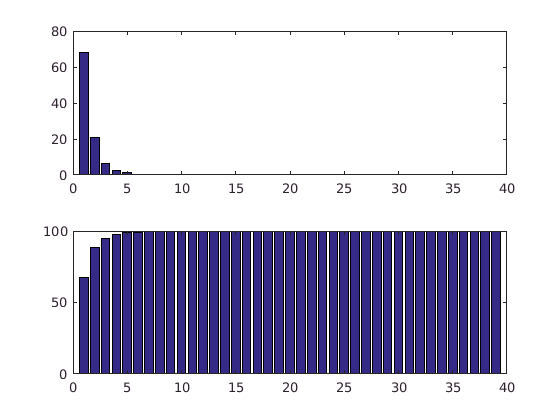

figure
subplot(211)
bar(explainedPM) % Variance explained by each PC

subplot(212)
bar(cumsum(explainedPM)) % Cumulative variace explained by PCs
ylim([0 100])

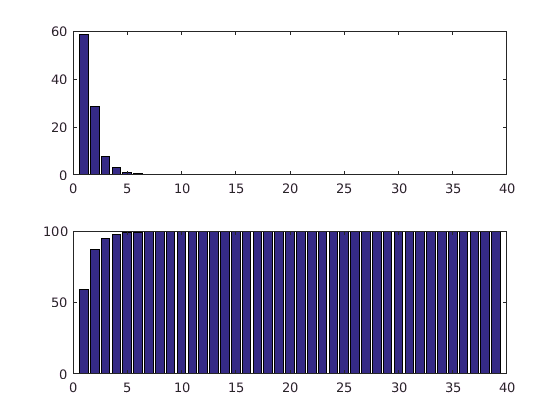


%Same for DL
figure
subplot(211)
bar(explainedDL) % Variance explained by each PC

subplot(212)
bar(cumsum(explainedDL)) % Cumulative variace explained by PCs
ylim([0 100])

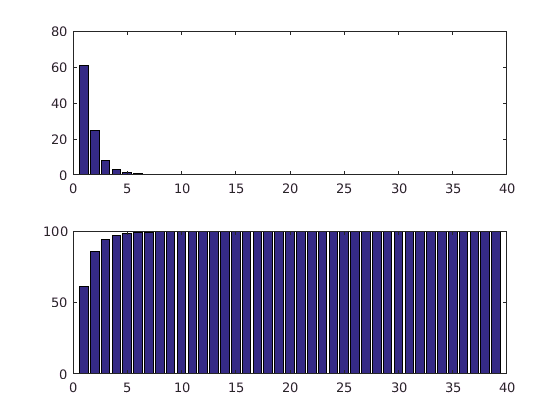


%Both together
figure
subplot(211)
bar(explained) % Variance explained by each PC

subplot(212)
bar(cumsum(explained)) % Cumulative variace explained by PCs
ylim([0 100])

## Get crossval inds

% get training indices and test indices
[trainingIdxPM,testingIdxPM] = crossvalind('LeaveMOut',height(tPM),round(0.2*height(tPM)));
[trainingIdxDL,testingIdxDL] = crossvalind('LeaveMOut',height(tDL),round(0.2*height(tDL)));

## Fit GLM to kinematics in each workspace and predict neural firing rates (for cross-validation)

% Decompose score from PCA into workspaces
scorePM = scores(1:height(tPM),1:5);
scoreDL = scores(height(tPM)+1:end,1:5);

kinModelPMR2 = zeros(1,width(neurPM));
kinModelDLR2 = zeros(1,width(neurDL));
kinModelAcrossDLR2 = zeros(1,width(neurDL));
kinModelAcrossPMR2 = zeros(1,width(neurDL));
kinModelFullPMR2 = zeros(1,width(neurDL));
kinModelFullDLR2 = zeros(1,width(neurDL));
muscleModelPMR2 = zeros(1,width(neurPM));
muscleModelDLR2 = zeros(1,width(neurDL));
muscleModelAcrossDLR2 = zeros(1,width(neurDL));
muscleModelAcrossPMR2 = zeros(1,width(neurDL));
muscleModelFullPMR2 = zeros(1,width(neurDL));
muscleModelFullDLR2 = zeros(1,width(neurPM));

% GLM inputs (only use velocities)
kinInputPM = kinPM{trainingIdxPM,3:4};
kinInputDL = kinDL{trainingIdxDL,3:4};
% muscleInputPM = [musclePM{trainingIdxPM,:} muscleVelPM{trainingIdxPM,:}];
% muscleInputDL = [muscleDL{trainingIdxDL,:} muscleVelDL{trainingIdxDL,:}];
muscleInputPM = scorePM(trainingIdxPM,:);
muscleInputDL = scoreDL(trainingIdxDL,:);
kinInputPMtest = kinPM{testingIdxPM,3:4};
kinInputDLtest = kinDL{testingIdxDL,3:4};
% muscleInputPMtest = [musclePM{testingIdxPM,:} muscleVelPM{testingIdxPM,:}];
% muscleInputDLtest = [muscleDL{testingIdxDL,:} muscleVelDL{testingIdxDL,:}];
muscleInputPMtest = scorePM(testingIdxPM,:);
muscleInputDLtest = scoreDL(testingIdxDL,:);

% Get times, just in case
tPMtrain = tPM.t(trainingIdxPM);
tDLtrain = tDL.t(trainingIdxDL);
tPMtest = tPM.t(testingIdxPM);
tDLtest = tDL.t(testingIdxDL);

% initialize neural predictions
kinPredNeurPMfromPM = zeros(sum(testingIdxPM),width(neurPM));
kinPredNeurPMfromDL = zeros(sum(testingIdxPM),width(neurPM));
kinPredNeurDLfromDL = zeros(sum(testingIdxDL),width(neurDL));
kinPredNeurDLfromPM = zeros(sum(testingIdxDL),width(neurDL));
kinPredNeurPMfromFull = zeros(sum(testingIdxPM),width(neurPM));
kinPredNeurDLfromFull = zeros(sum(testingIdxDL),width(neurDL));

musclePredNeurPMfromPM = zeros(sum(testingIdxPM),width(neurPM));
musclePredNeurPMfromDL = zeros(sum(testingIdxPM),width(neurPM));
musclePredNeurDLfromDL = zeros(sum(testingIdxDL),width(neurDL));
musclePredNeurDLfromPM = zeros(sum(testingIdxDL),width(neurDL));
musclePredNeurPMfromFull = zeros(sum(testingIdxPM),width(neurPM));
musclePredNeurDLfromFull = zeros(sum(testingIdxDL),width(neurDL));

% initialize weight matrices
tic;
for i = 1:width(neurPM)
    % compose GLM outputs
    outputPM = neurPM{trainingIdxPM,i};
    outputDL = neurDL{trainingIdxDL,i};
    outputPMtest = neurPM{testingIdxPM,i};
    outputDLtest = neurDL{testingIdxDL,i};
    
    % fit full GLM on PM and DL
    kinModelPM = fitglm(kinInputPM,outputPM,'Distribution','poisson');
    kinModelDL = fitglm(kinInputDL,outputDL,'Distribution','poisson');
    kinModelFull = fitglm([kinInputPM;kinInputDL],[outputPM;outputDL],'Distribution','poisson');
    muscleModelPM = fitglm(muscleInputPM,outputPM,'Distribution','poisson');
    muscleModelDL = fitglm(muscleInputDL,outputDL,'Distribution','poisson');
    muscleModelFull = fitglm([muscleInputPM;muscleInputDL],[outputPM;outputDL],'Distribution','poisson');
    
    % Get predicted neural outputs on test data
    kinPredNeurPMfromPM(:,i) = kinModelPM.predict(kinInputPMtest);
    kinPredNeurPMfromDL(:,i) = kinModelDL.predict(kinInputPMtest);
    kinPredNeurDLfromDL(:,i) = kinModelDL.predict(kinInputDLtest);
    kinPredNeurDLfromPM(:,i) = kinModelPM.predict(kinInputDLtest);
    kinPredNeurPMfromFull(:,i) = kinModelFull.predict(kinInputPMtest);
    kinPredNeurDLfromFull(:,i) = kinModelFull.predict(kinInputDLtest);
    
    musclePredNeurPMfromPM(:,i) = muscleModelPM.predict(muscleInputPMtest);
    musclePredNeurPMfromDL(:,i) = muscleModelDL.predict(muscleInputPMtest);
    musclePredNeurDLfromDL(:,i) = muscleModelDL.predict(muscleInputDLtest);
    musclePredNeurDLfromPM(:,i) = muscleModelPM.predict(muscleInputDLtest);
    musclePredNeurPMfromFull(:,i) = muscleModelFull.predict(muscleInputPMtest);
    musclePredNeurDLfromFull(:,i) = muscleModelFull.predict(muscleInputDLtest);
    
    % compute pseudoR2 on each model
    kinModelPMR2(i) = compute_pseudo_R2(outputPMtest,kinPredNeurPMfromPM(:,i),mean(outputPMtest));
    kinModelDLR2(i) = compute_pseudo_R2(outputDLtest,kinPredNeurDLfromDL(:,i),mean(outputDLtest));
    muscleModelPMR2(i) = compute_pseudo_R2(outputPMtest,musclePredNeurPMfromPM(:,i),mean(outputPMtest));
    muscleModelDLR2(i) = compute_pseudo_R2(outputDLtest,musclePredNeurDLfromDL(:,i),mean(outputDLtest));
    
    % test across
    kinModelAcrossDLR2(i) = compute_pseudo_R2(outputDLtest,kinPredNeurDLfromPM(:,i),mean(outputDLtest));
    kinModelAcrossPMR2(i) = compute_pseudo_R2(outputPMtest,kinPredNeurPMfromDL(:,i),mean(outputPMtest));
    muscleModelAcrossDLR2(i) = compute_pseudo_R2(outputDLtest,musclePredNeurDLfromPM(:,i),mean(outputDLtest));
    muscleModelAcrossPMR2(i) = compute_pseudo_R2(outputPMtest,musclePredNeurPMfromDL(:,i),mean(outputPMtest));
    
    % test full
    kinModelFullPMR2(i) = compute_pseudo_R2(outputPMtest,kinPredNeurPMfromFull(:,i),mean(outputPMtest));
    kinModelFullDLR2(i) = compute_pseudo_R2(outputDLtest,kinPredNeurDLfromFull(:,i),mean(outputDLtest));
    muscleModelFullPMR2(i) = compute_pseudo_R2(outputPMtest,musclePredNeurPMfromFull(:,i),mean(outputPMtest));
    muscleModelFullDLR2(i) = compute_pseudo_R2(outputDLtest,musclePredNeurDLfromFull(:,i),mean(outputDLtest));
end
toc

Elapsed time is 61.231170 seconds.


## Look at PM->PM fits

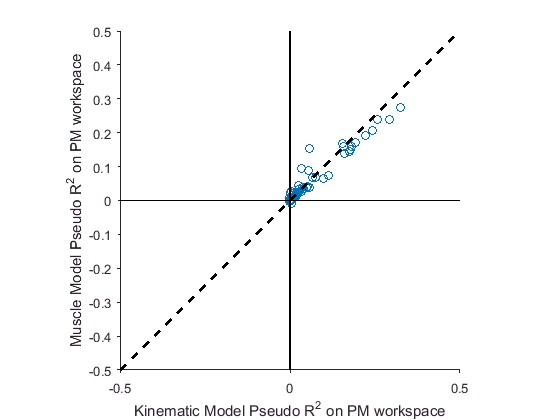

figure
plot(kinModelPMR2,muscleModelPMR2,'o')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',2)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
xlabel('Kinematic Model Pseudo R^2 on PM workspace')
ylabel('Muscle Model Pseudo R^2 on PM workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out')

## Look at PM->DL fits

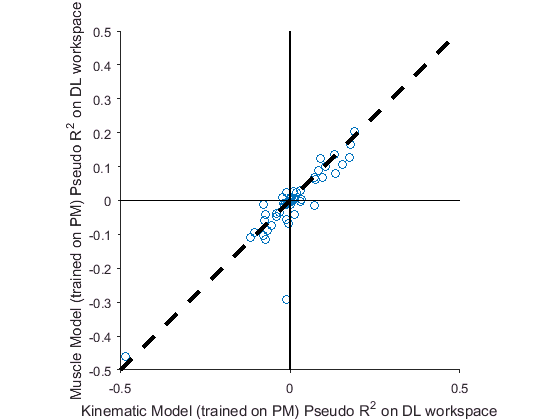

figure
plot(kinModelAcrossDLR2,muscleModelAcrossDLR2,'o')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
xlabel('Kinematic Model (trained on PM) Pseudo R^2 on DL workspace')
ylabel('Muscle Model (trained on PM) Pseudo R^2 on DL workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out')

## Look at Full->PM,DL fits

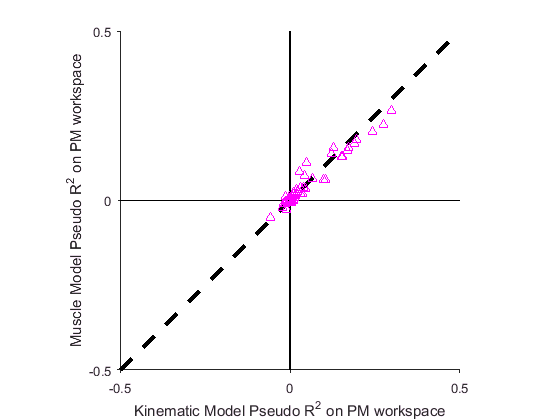

figure
plot(kinModelFullPMR2,muscleModelFullPMR2,'m^')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
plot(kinModelFullPMR2,muscleModelFullPMR2,'m^')
xlabel('Kinematic Model Pseudo R^2 on PM workspace')
ylabel('Muscle Model Pseudo R^2 on PM workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

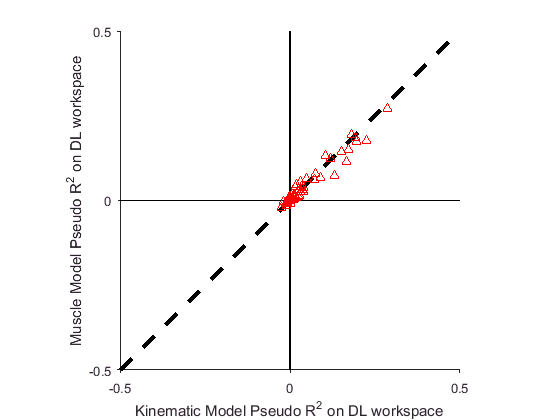

figure
plot(kinModelFullDLR2,muscleModelFullDLR2,'r^')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
plot(kinModelFullDLR2,muscleModelFullDLR2,'r^')
xlabel('Kinematic Model Pseudo R^2 on DL workspace')
ylabel('Muscle Model Pseudo R^2 on DL workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

## Full vs individual workspaces for kin and muscle models

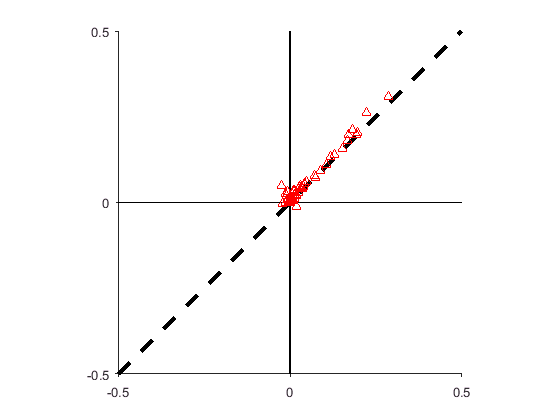

figure
plot(kinModelFullDLR2,kinModelDLR2,'r^')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
plot(kinModelFullDLR2,kinModelDLR2,'r^')
% xlabel('Kinematic Model Pseudo R^2 on DL workspace')
% ylabel('Muscle Model Pseudo R^2 on DL workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

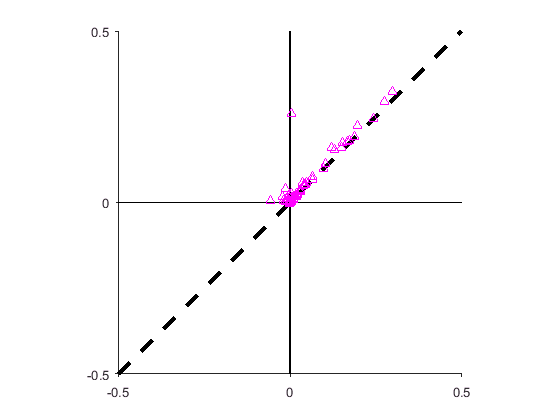


figure
plot(kinModelFullPMR2,kinModelPMR2,'m^')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
plot(kinModelFullPMR2,kinModelPMR2,'m^')
% xlabel('Kinematic Model Pseudo R^2 on DL workspace')
% ylabel('Muscle Model Pseudo R^2 on DL workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

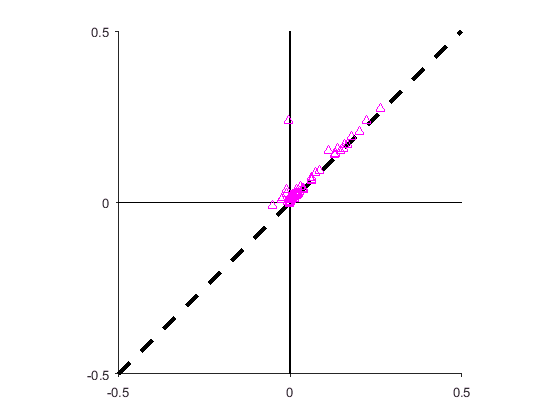


figure
plot(muscleModelFullPMR2,muscleModelPMR2,'m^')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
plot(muscleModelFullPMR2,muscleModelPMR2,'m^')
% xlabel('Kinematic Model Pseudo R^2 on DL workspace')
% ylabel('Muscle Model Pseudo R^2 on DL workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

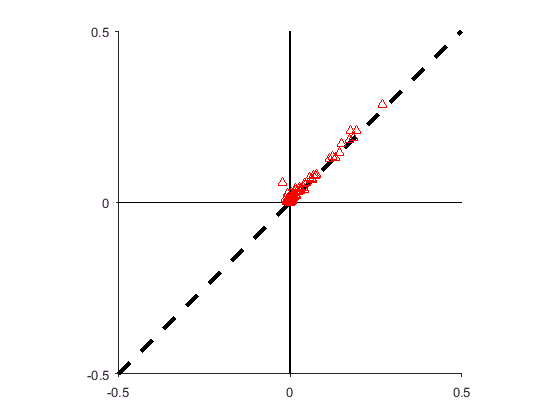


figure
plot(muscleModelFullDLR2,muscleModelDLR2,'r^')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
plot([0 0],[-1 1],'k-','linewidth',1)
plot([-1 1],[0 0],'k-','linewidth',1)
plot(muscleModelFullDLR2,muscleModelDLR2,'r^')
% xlabel('Kinematic Model Pseudo R^2 on DL workspace')
% ylabel('Muscle Model Pseudo R^2 on DL workspace')
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])
set(gca,'box','off','tickdir','out','xtick',[-0.5 0 0.5],'ytick',[-0.5 0 0.5])

## Predict tuning curves

% First get all tuning curves we want
[curvesPM,bins] = getTuningCurves(kinInputPMtest,neurPM{testingIdxPM,:});
[curvesDL,~] = getTuningCurves(kinInputDLtest,neurDL{testingIdxDL,:});

[kinPredCurvesPMfromPM,~] = getTuningCurves(kinInputPMtest,kinPredNeurPMfromPM);
[kinPredCurvesDLfromDL,~] = getTuningCurves(kinInputDLtest,kinPredNeurDLfromDL);
[kinPredCurvesPMfromDL,~] = getTuningCurves(kinInputPMtest,kinPredNeurPMfromDL);
[kinPredCurvesDLfromPM,~] = getTuningCurves(kinInputDLtest,kinPredNeurDLfromPM);
[kinPredCurvesPMfromFull,~] = getTuningCurves(kinInputPMtest,kinPredNeurPMfromFull);
[kinPredCurvesDLfromFull,~] = getTuningCurves(kinInputDLtest,kinPredNeurDLfromFull);

[musclePredCurvesPMfromPM,~] = getTuningCurves(kinInputPMtest,musclePredNeurPMfromPM);
[musclePredCurvesDLfromDL,~] = getTuningCurves(kinInputDLtest,musclePredNeurDLfromDL);
[musclePredCurvesPMfromDL,~] = getTuningCurves(kinInputPMtest,musclePredNeurPMfromDL);
[musclePredCurvesDLfromPM,~] = getTuningCurves(kinInputDLtest,musclePredNeurDLfromPM);
[musclePredCurvesPMfromFull,~] = getTuningCurves(kinInputPMtest,musclePredNeurPMfromFull);
[musclePredCurvesDLfromFull,~] = getTuningCurves(kinInputDLtest,musclePredNeurDLfromFull);


## Get predicted preferred directions

samplePdTable = repmat(table(0,[0 0],'VariableNames',{'velDir','velDirCI'}),width(neurPM),1);

PdsPM = samplePdTable;
PdsDL = samplePdTable;

kinPredPdsPMfromPM = samplePdTable;
kinPredPdsDLfromDL = samplePdTable;
kinPredPdsPMfromDL = samplePdTable;
kinPredPdsDLfromPM = samplePdTable;
kinPredPdsPMfromFull = samplePdTable;
kinPredPdsDLfromFull = samplePdTable;

musclePredPdsPMfromPM = samplePdTable;
musclePredPdsDLfromDL = samplePdTable;
musclePredPdsPMfromDL = samplePdTable;
musclePredPdsDLfromPM = samplePdTable;
musclePredPdsPMfromFull = samplePdTable;
musclePredPdsDLfromFull = samplePdTable;

tic;
for i = 1:width(neurPM)
    % compose GLM outputs
    outputPMtest = neurPM{testingIdxPM,i};
    outputDLtest = neurDL{testingIdxDL,i};
    
    % bootstrap all fits
%     kinModelPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputPMtest,outputPMtest);
%     kinModelDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputDLtest,outputDLtest);
%     
%     kinModelPMfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputPMtest,kinPredNeurPMfromPM(:,i));
%     kinModelDLfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputDLtest,kinPredNeurDLfromDL(:,i));
%     kinModelPMfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputPMtest,kinPredNeurPMfromDL(:,i));
%     kinModelDLfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputDLtest,kinPredNeurDLfromPM(:,i));
%     kinModelPMfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputPMtest,kinPredNeurPMfromFull(:,i));
%     kinModelDLfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputDLtest,kinPredNeurDLfromFull(:,i));
%     
%     muscleModelPMfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputPMtest,musclePredNeurPMfromPM(:,i));
%     muscleModelDLfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputDLtest,musclePredNeurDLfromDL(:,i));
%     muscleModelPMfromDL = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputPMtest,musclePredNeurPMfromDL(:,i));
%     muscleModelDLfromPM = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputDLtest,musclePredNeurDLfromPM(:,i));
%     muscleModelPMfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputPMtest,musclePredNeurPMfromFull(:,i));
%     muscleModelDLfromFull = bootstrp(bootreps,@(X,Y) bootfunc(X,y),kinInputDLtest,musclePredNeurDLfromFull(:,i));
    
    % extract weights
    
    PdsPM(i,:) = calculatePDs(kinInputPMtest,outputPMtest,true,100);
    PdsDL(i,:) = calculatePDs(kinInputDLtest,outputDLtest,true,100);
    
    kinPredPdsPMfromPM(i,:) = calculatePDs(kinInputPMtest,kinPredNeurPMfromPM(:,i),true,100);
    kinPredPdsDLfromDL(i,:) = calculatePDs(kinInputDLtest,kinPredNeurDLfromDL(:,i),true,100);
    kinPredPdsPMfromDL(i,:) = calculatePDs(kinInputPMtest,kinPredNeurPMfromDL(:,i),true,100);
    kinPredPdsDLfromPM(i,:) = calculatePDs(kinInputDLtest,kinPredNeurDLfromPM(:,i),true,100);
    kinPredPdsPMfromFull(i,:) = calculatePDs(kinInputPMtest,kinPredNeurPMfromFull(:,i),true,100);
    kinPredPdsDLfromFull(i,:) = calculatePDs(kinInputDLtest,kinPredNeurDLfromFull(:,i),true,100);
    
    musclePredPdsPMfromPM(i,:) = calculatePDs(kinInputPMtest,musclePredNeurPMfromPM(:,i),true,100);
    musclePredPdsDLfromDL(i,:) = calculatePDs(kinInputDLtest,musclePredNeurDLfromDL(:,i),true,100);
    musclePredPdsPMfromDL(i,:) = calculatePDs(kinInputPMtest,musclePredNeurPMfromDL(:,i),true,100);
    musclePredPdsDLfromPM(i,:) = calculatePDs(kinInputDLtest,musclePredNeurDLfromPM(:,i),true,100);
    musclePredPdsPMfromFull(i,:) = calculatePDs(kinInputPMtest,musclePredNeurPMfromFull(:,i),true,100);
    musclePredPdsDLfromFull(i,:) = calculatePDs(kinInputDLtest,musclePredNeurDLfromFull(:,i),true,100);
end

toc
    


## Predict tuning curves within workspace using kin and muscle models

Find that muscle model seems to match the kinematic model tuning curves fairly well. Both predict the actual tuning curves decently.

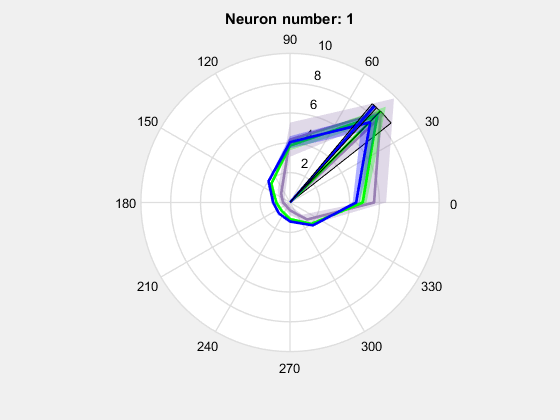

colorPM = [0.6 0.5 0.7];
colorDL = [1 0 0];
colorPredKin =  [0 1 0];
colorPredMuscle = [0 0 1];

figure

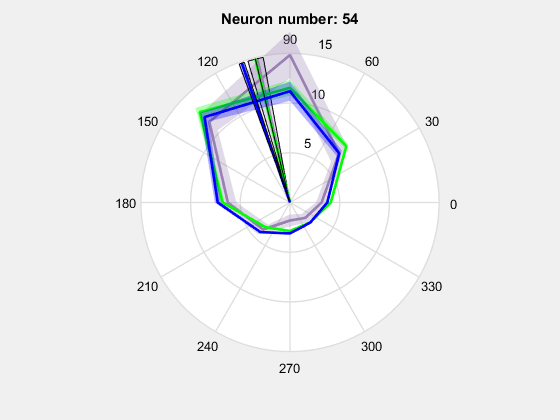

for i = 1:height(curvesPM)
    clf
    maxRad = max([curvesPM.binnedFR(i,:) kinPredCurvesPMfromPM.binnedFR(i,:) musclePredCurvesPMfromPM.binnedFR(i,:)]);
    
    plotTuning(bins,PdsPM(i,:),curvesPM(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,kinPredPdsPMfromPM(i,:),kinPredCurvesPMfromPM(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredPdsPMfromPM(i,:),musclePredCurvesPMfromPM(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end

## Same for DL

for i = 1:height(curvesDL)
    clf
    maxRad = max([curvesDL.binnedFR(i,:) kinPredCurvesDLfromDL.binnedFR(i,:) musclePredCurvesDLfromDL.binnedFR(i,:)]);
    
    plotTuning(bins,PdsDL(i,:),curvesDL(i,:),maxRad,colorDL)
    hold on
    plotTuning(bins,kinPredPdsDLfromDL(i,:),kinPredCurvesDLfromDL(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredPdsDLfromDL(i,:),musclePredCurvesDLfromDL(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end

## Try predicting opposite workspace tuning curves

for i = 1:height(curvesPM)
    clf
    maxRad = max([curvesPM.binnedFR(i,:) kinPredCurvesPMfromDL.binnedFR(i,:) musclePredCurvesPMfromDL.binnedFR(i,:)]);
    
    plotTuning(bins,PdsPM(i,:),curvesPM(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,kinPredPdsPMfromDL(i,:),kinPredCurvesPMfromDL(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredPdsPMfromDL(i,:),musclePredCurvesPMfromDL(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted

## Same for DL (opposite)

for i = 1:height(curvesDL)
    clf
    maxRad = max([curvesDL.binnedFR(i,:) kinPredCurvesDLfromPM.binnedFR(i,:) musclePredCurvesDLfromPM.binnedFR(i,:)]);
    
    plotTuning(bins,PdsDL(i,:),curvesDL(i,:),maxRad,colorDL)
    hold on
    plotTuning(bins,kinPredPdsDLfromPM(i,:),kinPredCurvesDLfromPM(i,:),maxRad,colorPredKin)
    plotTuning(bins,musclePredPdsDLfromPM(i,:),musclePredCurvesDLfromPM(i,:),maxRad,colorPredMuscle)
    title(['Neuron number: ' num2str(i)])
    waitforbuttonpress
end

## Plot PM-DL comparison tuning curves

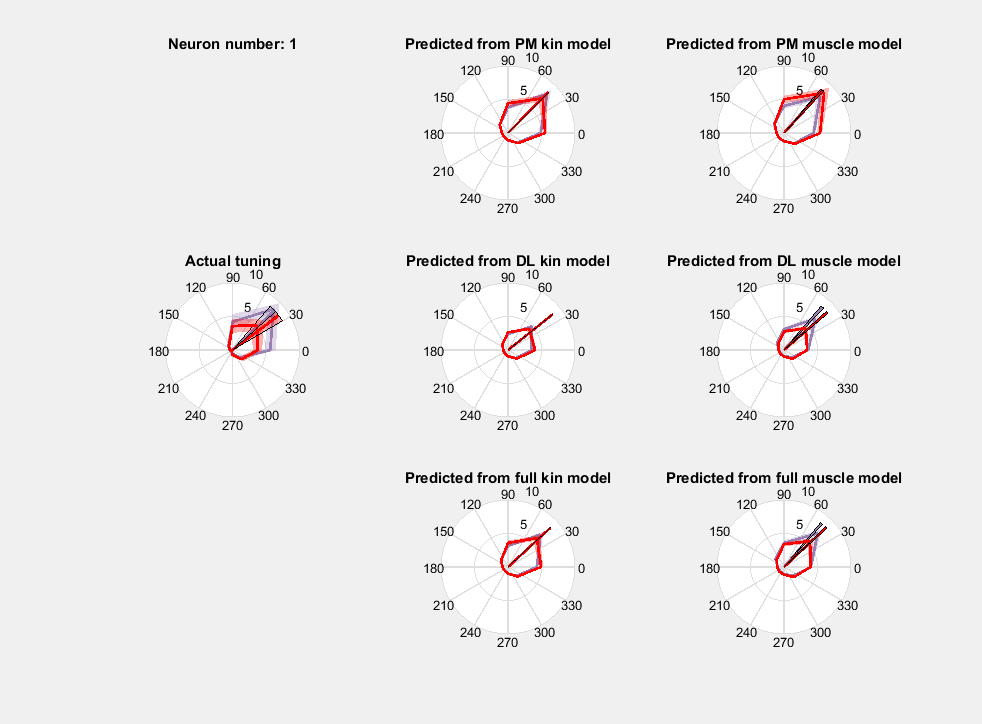

figure

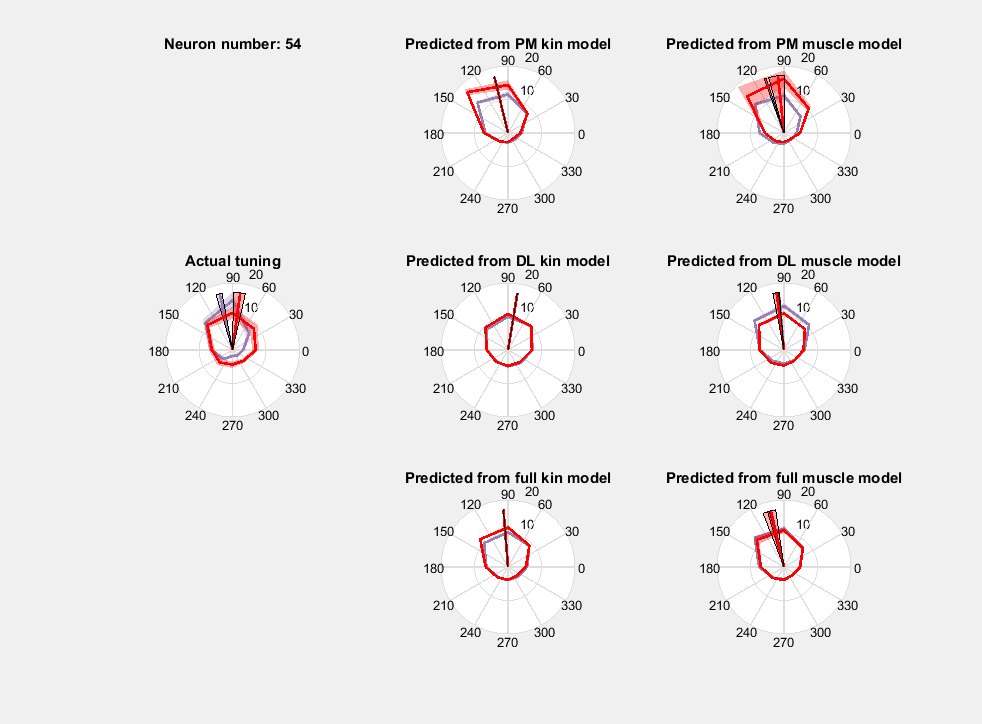

for i = 1:height(curvesDL)
    clf
    maxRad = max([curvesPM.binnedFR(i,:) curvesDL.binnedFR(i,:)...
        kinPredCurvesDLfromPM.binnedFR(i,:) musclePredCurvesDLfromPM.binnedFR(i,:)...
        kinPredCurvesPMfromPM.binnedFR(i,:) musclePredCurvesPMfromPM.binnedFR(i,:)...
        kinPredCurvesPMfromDL.binnedFR(i,:) musclePredCurvesPMfromDL.binnedFR(i,:)...
        kinPredCurvesDLfromDL.binnedFR(i,:) musclePredCurvesDLfromDL.binnedFR(i,:)...
        kinPredCurvesPMfromFull.binnedFR(i,:) musclePredCurvesPMfromFull.binnedFR(i,:)...
        kinPredCurvesDLfromFull.binnedFR(i,:) musclePredCurvesDLfromFull.binnedFR(i,:)]);
    
    subplot(331)
    title(['Neuron number: ' num2str(i)])
    axis off
    
    subplot(334)
    plotTuning(bins,PdsPM(i,:),curvesPM(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,PdsDL(i,:),curvesDL(i,:),maxRad,colorDL)
    title('Actual tuning')
    
    subplot(332)
    plotTuning(bins,kinPredPdsPMfromPM(i,:),kinPredCurvesPMfromPM(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,kinPredPdsDLfromPM(i,:),kinPredCurvesDLfromPM(i,:),maxRad,colorDL)
    title('Predicted from PM kin model')
    
    subplot(333)
    plotTuning(bins,musclePredPdsPMfromPM(i,:),musclePredCurvesPMfromPM(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,musclePredPdsDLfromPM(i,:),musclePredCurvesDLfromPM(i,:),maxRad,colorDL)
    title('Predicted from PM muscle model')
    
    subplot(335)
    plotTuning(bins,kinPredPdsPMfromDL(i,:),kinPredCurvesPMfromDL(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,kinPredPdsDLfromDL(i,:),kinPredCurvesDLfromDL(i,:),maxRad,colorDL)
    title('Predicted from DL kin model')
    
    subplot(336)
    plotTuning(bins,musclePredPdsPMfromDL(i,:),musclePredCurvesPMfromDL(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,musclePredPdsDLfromDL(i,:),musclePredCurvesDLfromDL(i,:),maxRad,colorDL)
    title('Predicted from DL muscle model')
    
    subplot(338)
    plotTuning(bins,kinPredPdsPMfromFull(i,:),kinPredCurvesPMfromFull(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,kinPredPdsDLfromFull(i,:),kinPredCurvesDLfromFull(i,:),maxRad,colorDL)
    title('Predicted from full kin model')
    
    subplot(339)
    plotTuning(bins,musclePredPdsPMfromFull(i,:),musclePredCurvesPMfromFull(i,:),maxRad,colorPM)
    hold on
    plotTuning(bins,musclePredPdsDLfromFull(i,:),musclePredCurvesDLfromFull(i,:),maxRad,colorDL)
    title('Predicted from full muscle model')
    
    waitforbuttonpress
end

## Plot example neuron

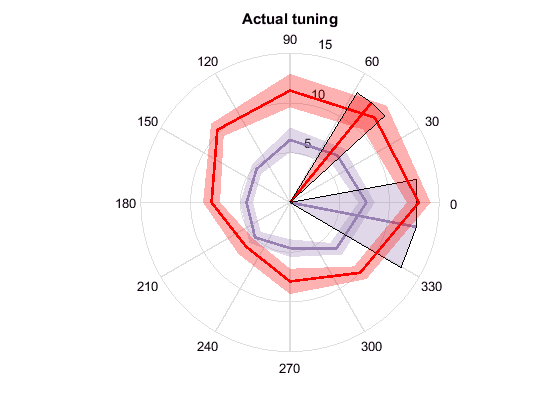

figure
i = 5;
clf
maxRad = max([curvesPM.binnedFR(i,:) curvesDL.binnedFR(i,:)...
    kinPredCurvesDLfromPM.binnedFR(i,:) musclePredCurvesDLfromPM.binnedFR(i,:)...
    kinPredCurvesPMfromPM.binnedFR(i,:) musclePredCurvesPMfromPM.binnedFR(i,:)...
    kinPredCurvesPMfromDL.binnedFR(i,:) musclePredCurvesPMfromDL.binnedFR(i,:)...
    kinPredCurvesDLfromDL.binnedFR(i,:) musclePredCurvesDLfromDL.binnedFR(i,:)...
    kinPredCurvesPMfromFull.binnedFR(i,:) musclePredCurvesPMfromFull.binnedFR(i,:)...
    kinPredCurvesDLfromFull.binnedFR(i,:) musclePredCurvesDLfromFull.binnedFR(i,:)]);

figure(334)
plotTuning(bins,PdsPM(i,:),curvesPM(i,:),maxRad,colorPM)
hold on
plotTuning(bins,PdsDL(i,:),curvesDL(i,:),maxRad,colorDL)
title('Actual tuning')

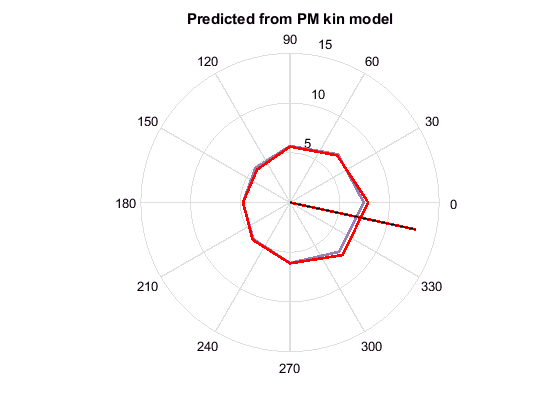


figure(332)
plotTuning(bins,kinPredPdsPMfromPM(i,:),kinPredCurvesPMfromPM(i,:),maxRad,colorPM)
hold on
plotTuning(bins,kinPredPdsDLfromPM(i,:),kinPredCurvesDLfromPM(i,:),maxRad,colorDL)
title('Predicted from PM kin model')

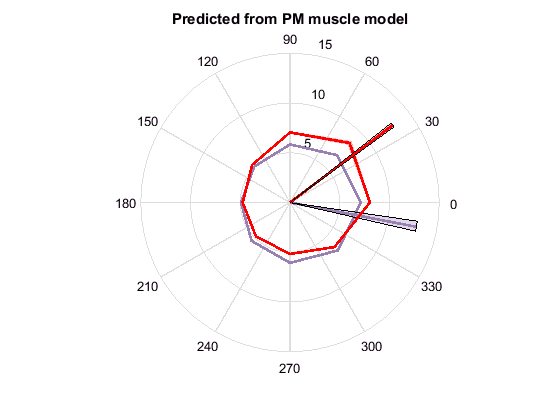


figure(333)
plotTuning(bins,musclePredPdsPMfromPM(i,:),musclePredCurvesPMfromPM(i,:),maxRad,colorPM)
hold on
plotTuning(bins,musclePredPdsDLfromPM(i,:),musclePredCurvesDLfromPM(i,:),maxRad,colorDL)
title('Predicted from PM muscle model')

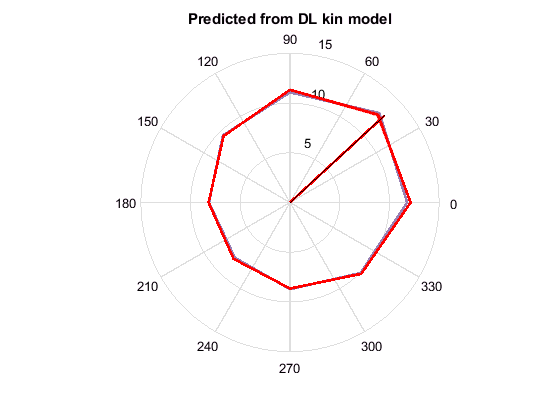


figure(335)
plotTuning(bins,kinPredPdsPMfromDL(i,:),kinPredCurvesPMfromDL(i,:),maxRad,colorPM)
hold on
plotTuning(bins,kinPredPdsDLfromDL(i,:),kinPredCurvesDLfromDL(i,:),maxRad,colorDL)
title('Predicted from DL kin model')

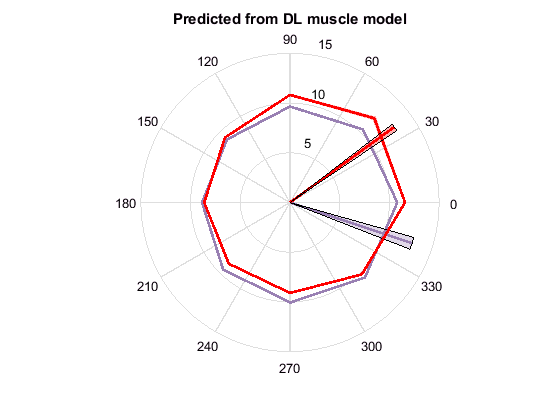


figure(336)
plotTuning(bins,musclePredPdsPMfromDL(i,:),musclePredCurvesPMfromDL(i,:),maxRad,colorPM)
hold on
plotTuning(bins,musclePredPdsDLfromDL(i,:),musclePredCurvesDLfromDL(i,:),maxRad,colorDL)
title('Predicted from DL muscle model')

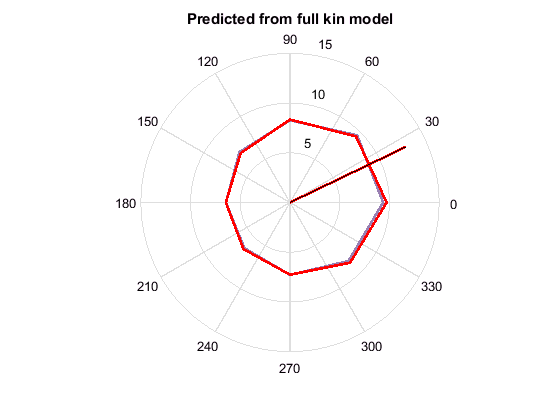


figure(338)
plotTuning(bins,kinPredPdsPMfromFull(i,:),kinPredCurvesPMfromFull(i,:),maxRad,colorPM)
hold on
plotTuning(bins,kinPredPdsDLfromFull(i,:),kinPredCurvesDLfromFull(i,:),maxRad,colorDL)
title('Predicted from full kin model')

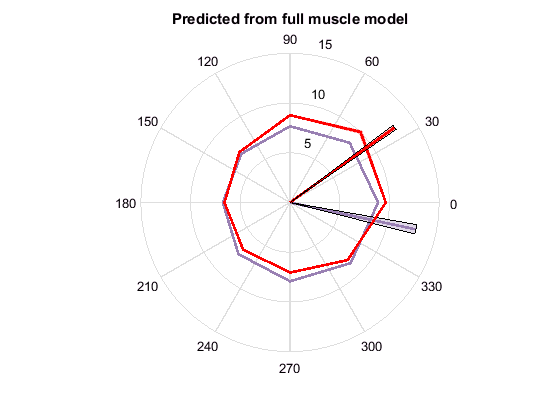


figure(339)
plotTuning(bins,musclePredPdsPMfromFull(i,:),musclePredCurvesPMfromFull(i,:),maxRad,colorPM)
hold on
plotTuning(bins,musclePredPdsDLfromFull(i,:),musclePredCurvesDLfromFull(i,:),maxRad,colorDL)
title('Predicted from full muscle model')

## Iris plots for all models

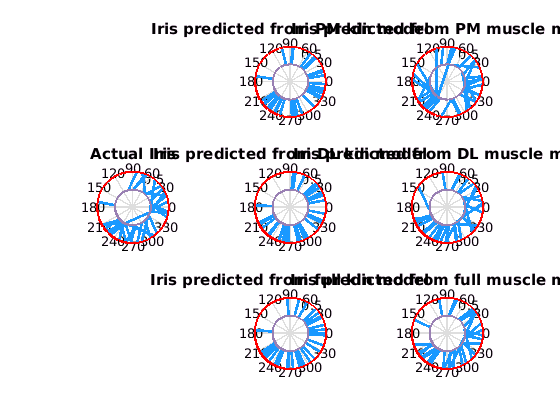

figure
subplot(334)
% use this plot to inform which neurons to plot for the models
which_neurons = irisPlot(PdsPM,PdsDL,[]);
title('Actual Iris')

subplot(332)
irisPlot(kinPredPdsPMfromPM,kinPredPdsDLfromPM, which_neurons);
title('Iris predicted from PM kin model')

subplot(333)
irisPlot(musclePredPdsPMfromPM,musclePredPdsDLfromPM, which_neurons);
title('Iris predicted from PM muscle model')

subplot(335)
irisPlot(kinPredPdsPMfromDL,kinPredPdsDLfromDL, which_neurons);
title('Iris predicted from DL kin model')

subplot(336)
irisPlot(musclePredPdsPMfromDL,musclePredPdsDLfromDL, which_neurons);
title('Iris predicted from DL muscle model')

subplot(338)
irisPlot(kinPredPdsPMfromFull,kinPredPdsDLfromFull, which_neurons);
title('Iris predicted from full kin model')

subplot(339)
test = irisPlot(musclePredPdsPMfromFull,musclePredPdsDLfromFull, which_neurons);
title('Iris predicted from full muscle model')

## Make simpler iris plot comparison

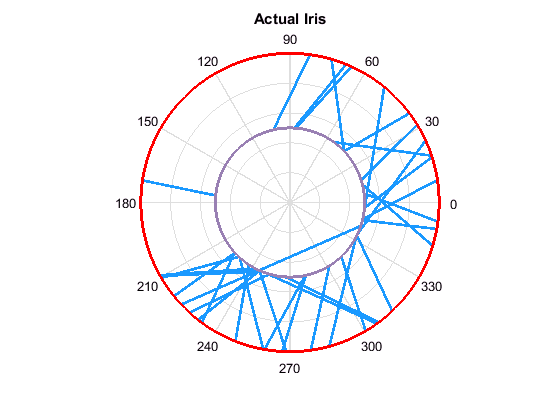

% figure
figure(131)
which_neurons = irisPlot(PdsPM,PdsDL,[]);
title('Actual Iris')

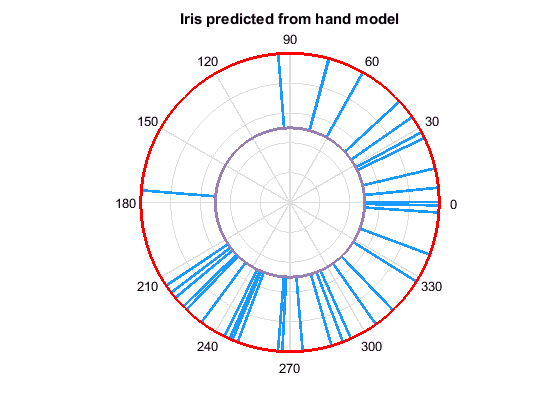


figure(132)
irisPlot(kinPredPdsPMfromFull,kinPredPdsDLfromFull,which_neurons);
title('Iris predicted from hand model')

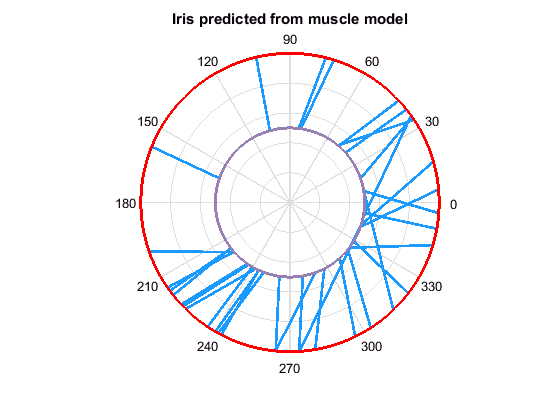


figure(133)
irisPlot(musclePredPdsPMfromFull,musclePredPdsDLfromFull,which_neurons);
title('Iris predicted from muscle model')

## test iris

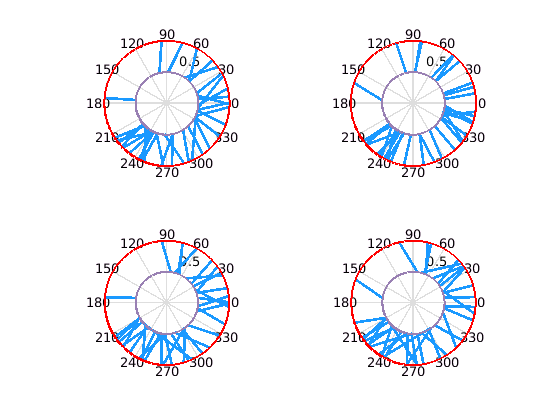

figure
subplot(221)
irisPlot(PdsPM, kinPredPdsPMfromFull,which_neurons);

subplot(222)
irisPlot(PdsPM,musclePredPdsPMfromFull,which_neurons);

subplot(223)
irisPlot(PdsDL, kinPredPdsDLfromFull,which_neurons);

subplot(224)
irisPlot(PdsDL,musclePredPdsDLfromFull,which_neurons);

## hitograms of delta PD

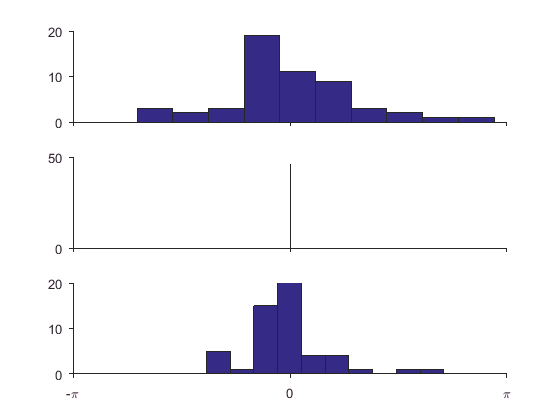

diffPD = PdsDL.velDir - PdsPM.velDir;
diffPD(diffPD<-pi) = diffPD(diffPD<-pi)+2*pi;
diffPD(diffPD>pi) = diffPD(diffPD>pi)-2*pi;

kinPredDiffPDfromFull = kinPredPdsDLfromFull.velDir - kinPredPdsPMfromFull.velDir;
kinPredDiffPDfromFull(kinPredDiffPDfromFull<-pi) = kinPredDiffPDfromFull(kinPredDiffPDfromFull<-pi)+2*pi;
kinPredDiffPDfromFull(kinPredDiffPDfromFull>pi) = kinPredDiffPDfromFull(kinPredDiffPDfromFull>pi)-2*pi;

musclePredDiffPDfromFull = musclePredPdsDLfromFull.velDir - musclePredPdsPMfromFull.velDir;
musclePredDiffPDfromFull(musclePredDiffPDfromFull<-pi) = musclePredDiffPDfromFull(musclePredDiffPDfromFull<-pi)+2*pi;
musclePredDiffPDfromFull(musclePredDiffPDfromFull>pi) = musclePredDiffPDfromFull(musclePredDiffPDfromFull>pi)-2*pi;

figure
subplot(311)
hist(diffPD)
xlim([-pi pi])
ylim([0 20])
set(gca,'box','off','tickdir','out','xtick',[-pi 0 pi],'xticklabel',{})

subplot(312)
hist(kinPredDiffPDfromFull)
xlim([-pi pi])
set(gca,'box','off','tickdir','out','xtick',[-pi 0 pi],'xticklabel',{})

subplot(313)
hist(musclePredDiffPDfromFull)
xlim([-pi pi])
ylim([0 20])
set(gca,'box','off','tickdir','out','xtick',[-pi 0 pi],'xticklabel',{'-\pi','0','\pi'})

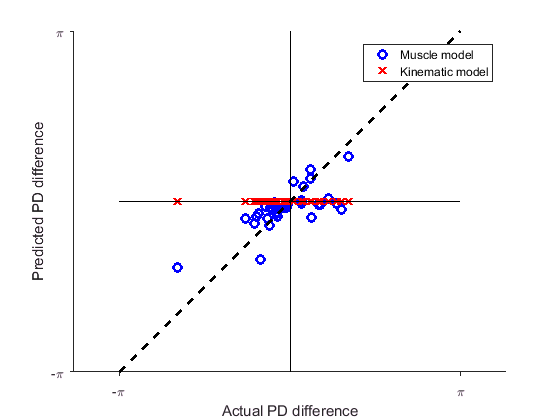


figure
plot(diffPD(which_neurons),musclePredDiffPDfromFull(which_neurons),'bo','linewidth',2)
hold on
plot(diffPD(which_neurons),kinPredDiffPDfromFull(which_neurons),'rx','linewidth',2)
plot([-pi pi],[-pi pi],'k--','linewidth',2)
plot([0 0],[-pi pi],'k-')
plot([-pi pi],[0 0],'k-')
% xlim([-pi pi])
% ylim([-pi pi])
axis equal
set(gca,'box','off','tickdir','out','xtick',[-pi pi],'ytick',[-pi pi],'xticklabel',{'-\pi','\pi'},'yticklabel',{'-\pi','\pi'})
% axis off
xlabel('Actual PD difference')
ylabel('Predicted PD difference')
legend('Muscle model','Kinematic model')